# Automated UAV rectification workflow - CIRN

Video files must be in folders YYYYMMDD_Location and subfolders for every flight

GCP must either be already processed into gps_northings.txt file or stored in a GCP folder

========================================================================

## Requirements

ffmpeg - [https://www.ffmpeg.org/](https://www.ffmpeg.org/)

exiftool - [https://exiftool.org/](https://exiftool.org/)

## To Do

- what type of input data formats are required?

- what other data input types should be included?

## Housekeeping

- confirm CODES path

- confirm DATA path - which day or multiple days are you processing

- get user email 

clearvars

global_dir = uigetdir('.', 'UAV Rectification');
setenv('PATH', [getenv('PATH') ':/usr/local/bin']);

Check for CODES folder dependencies

code_dir = [global_dir '/CODES'];
% Check that required rectification codes are downloaded.
if ~exist([code_dir '/CIRN'], 'dir')
    disp('Please download CIRN codes from GitHub.')
end
% Check that cBathy codes are downloaded.
if ~exist([code_dir '/cBathy_2.0'], 'dir')
    disp('Please download cBathy v2.0 codes from GitHub.')
end

Please download cBathy v2.0 codes from GitHub.


% Check that basic Functions are downloaded.
if ~exist([code_dir '/basicFunctions'], 'dir')
    disp('Please download basicFunctions codes from GitHub.')
end

addpath(genpath(code_dir))

Load which data folders are to be processed

data_dir = [global_dir '/DATA'];

% Load in all days that need to be processed.
data_files = dir(data_dir); data_files([data_files.isdir]==0)=[]; data_files(contains({data_files.name}, '.'))=[];
[ind_datafiles,~] = listdlg('ListString',{data_files.name}, 'SelectionMode','multiple', 'InitialValue',1, 'PromptString', {'Which days would you like to process?'});
data_files = data_files(ind_datafiles);

Get user email

user_email = inputdlg({'Name', 'Email'});
save([global_dir '/processing_run_' char(string(datetime('today')))], '*_dir', 'data_files', 'user_email')

## For each flight - get input data 

- Choose camera intrinsics file (all flights for a given day must be used with the same drone)

- Grid & transect coordinates - can be input or from file

- Local or world coordinates?

- dx

grid =    32.9272 -117.2596  700.0000  800.0000  262.0100    5.0000


ans = '2 Hz data can be pulled from 10 Hz data'

ans = '10 Hz data can be pulled from 10 Hz data'

    7 image files read


ans = 0

C = 7×11 table
                                              SourceFile                                                   FileName              CreateDate           Duration    CameraPitch    CameraYaw    CameraRoll    AbsoluteAltitude    RelativeAltitude             GPSLatitude                      GPSLongitude         
    _______________________________________________________________________________________________    ________________    _______________________    ________    ___________    _________    __________    ________________    ________________    _____________________________    ______________________________

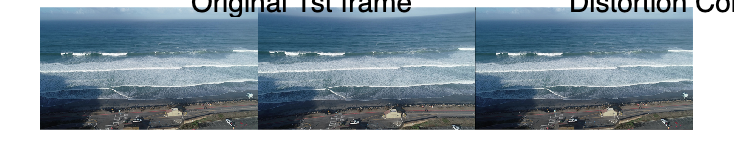

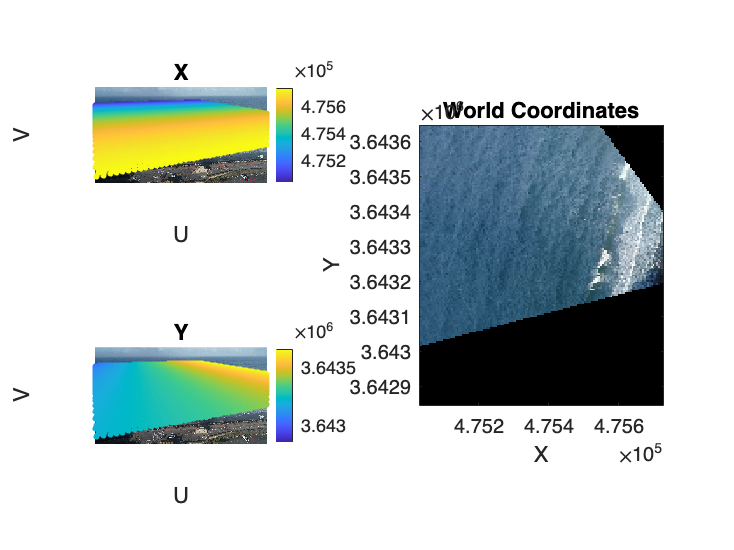

Operands to the logical AND (&&) and OR (||) operators must be convertible to logical scalar values. Use the ANY or ALL functions to reduce operands to logical scalar values.


for dd = 1:length(data_files)
    clearvars -except dd *_dir user_email data_files
    cd([data_files(dd).folder '/' data_files(dd).name])
    

Confirm Intrinsics file for each day of flights

    answer = questdlg('Has the camera been calibrated?', ...
        'Camera Calibration', ...
	    'Yes', 'No', ...
        'Yes');
    switch answer
        case 'Yes'
            [temp_file, temp_file_path] = uigetfile(global_dir, 'Camera Parameters');
            load(fullfile(temp_file_path, temp_file)); clear temp_file*
        case 'No'
            disp('Please calibrate camera to proceed.')
            break
    end

What data do you want to be processed? 2Hz, 10Hz, etc...

    info_Hz = inputdlg({'What Hz level do you want to extract at? (i.e. 2, 10)'});
    info_Hz = double(split(string(info_Hz), ','));
    if max(info_Hz) > 30
        disp('Maximum frame rate is 30Hz - anything faster will be removed.')
        info_Hz(info_Hz > 30) = [];
    end

Create grid file

   answer = questdlg('Local or World Coordinates?', ...
        'Local or World', ...
	    'Local', 'World', ...
        'World');
    switch answer
        case 'Local'
            localFlagInput = 1;
            grid_temp = inputdlg({'Cross-shore Distance (m)', 'Alongshore Distance (m)', 'dxdy'});
            grid([1 2 5]) = [0 0 270];
            grid([3 4 6]) = double(string(grid_temp)); clear grid_temp
            x2 = 0; y2 = 0;
        case 'World'
            localFlagInput = 0;
            answer2 = questdlg('Do you have a .mat grid file?', ...
                     'Grid file', ...
	                 'Yes', 'No', ...
                     'Yes');
            switch answer2
                case 'Yes'
                    [temp_file, temp_file_path] = uigetfile(global_dir, 'Grid file');
                    load(fullfile(temp_file_path, temp_file)); clear temp_file*
                    grid_temp = inputdlg({'dxdy'});
                    grid(6) = double(string(grid_temp)); clear grid_temp
                case 'No'
                    grid = inputdlg({'Latitude of Origin', 'Longitude of Origin', 'Cross-shore Distance (m)', 'Alongshore Distance (m)', 'Angle', 'dxdy'});
                    grid = double(string(grid));
            end % .mat grid file

        grid = str2double(string(grid));
        lat = grid(1); % N
        long = grid(2);% W
        [y2,x2, ~] = ll_to_utm(lat, long);
    
      
    end % Local or World Coordinates
    
    localOrigin = [x2,  y2];
    localAngle = 270-grid(5);

    ixlim = [x2-grid(3) x2];
    iylim = [y2-grid(4)/2 y2+grid(4)/2];

    idxdy = grid(6); 
    

Save all day info

    flights = dir([data_files(dd).folder '/' data_files(dd).name]); flights([flights.isdir]==0)=[]; flights(contains({flights.name}, '.'))=[]; flights(contains({flights.name}, 'GCP'))=[];
    save([data_files(dd).folder '/' data_files(dd).name '/input_data.mat'],...
        'cameraParams*', 'info_Hz', 'localFlagInput', 'grid', 'ixlim', 'iylim', 'idxdy', 'local*', 'flights')

Process each flight

    
    for ff = 1:length(flights)
        clearvars -except dd ff *_dir user_email data_files
        load([data_files(dd).folder '/' data_files(dd).name '/input_data.mat'])
        
        odir = [flights(ff).folder '/' flights(ff).name];
        oname = [data_files(dd).name '_' flights(ff).name];
        cd(odir) 
        if ~exist([odir '/Processed_data'], 'dir')
            mkdir 'Processed_data'
        end
      

Check how many set of images we need to extract - e.g. 2Hz images can be pulled from 10Hz, but 3Hz cannot

        extract_Hz = max(info_Hz);
        for hh = 1:length(info_Hz)
            if rem(max(info_Hz), info_Hz(hh)) == 0
                sprintf('%i Hz data can be pulled from %i Hz data', info_Hz(hh), max(info_Hz))
            else
                sprintf('%i Hz data CANNOT be pulled from %i Hz data', info_Hz(hh), max(info_Hz))
                extract_Hz = [extract_Hz info_Hz(hh)];
            end
        end
        for hh = 1:length(extract_Hz)
            if ~exist(sprintf('images_%iHz', extract_Hz(hh)), 'dir')
                mkdir(sprintf('images_%iHz', extract_Hz(hh)))
            end
        end

Pull initial drone coordinates and which movies to process from metadata

        system(sprintf('exiftool -filename -CreateDate -Duration -CameraPitch -CameraYaw -CameraRoll -AbsoluteAltitude -RelativeAltitude -GPSLatitude -GPSLongitude -csv -c "%%.20f" %s/DJI_0* > %s/%s', odir, odir, [oname '.csv']));
        
        C = readtable(fullfile(odir, [oname '.csv']))
        format long
        % get indices of images and videos to extract from
        form = char(C.FileName);
        form = string(form(:,end-2:end));
        mov_id = find(form == 'MOV'); 
        jpg_id = find(form == 'JPG');
    
        % required: starting on full video 5:28 for DJI
        i_temp = find(C.Duration(mov_id) == duration(0,5,28)); mov_id(1:i_temp(1)-1)=[];
        i_temp = find(isnan(C.Duration(mov_id))); mov_id(i_temp)=[];
    
        % if image taken at beginning & end of flight - use beginning image
        if length(jpg_id) > 1;jpg_id = jpg_id(1); end
        % if no image taken, use mov_id
        if isempty(jpg_id); jpg_id = mov_id(1); end
    
        %  
        % pull RTK-GPS coordinates from image and change to Eastings/Northings
        % requires intg2012b and ll_to_utm codes (in basi
        lat = char(C.GPSLatitude(jpg_id));
        lat = str2double(lat(1:10));
        long = char(C.GPSLongitude(jpg_id));
        if long(end) == 'W'
            long = str2double(['-' long(1:11)]);
        else
            long = str2double(long(1:11));
        end
        [zgeoid_offset] = intg2012b(code_dir, lat,long);
        [UTMNorthing, UTMEasting, UTMZone] = ll_to_utm(lat, long);
        extrinsicsInitialGuess = [UTMEasting UTMNorthing C.RelativeAltitude(jpg_id)-zgeoid_offset deg2rad(C.CameraYaw(mov_id(1))+360) deg2rad(C.CameraPitch(mov_id(1))+90) deg2rad(C.CameraRoll(mov_id(1)))]; % [ x y z azimuth tilt swing]
        
    
        save(fullfile(odir, 'Processed_data', 'Inital_coordinates'), 'extrinsicsInitialGuess', 'UTMNorthing', 'UTMEasting', 'zgeoid_offset', 'jpg_id', 'mov_id', 'lat', 'long', 'C')

Extract 1st frame to use as example

        if ~exist([odir '/Initial_frame.jpg'], 'file')    
            system(['ffmpeg -ss 00:00:01 -i ' char(string(C.FileName(mov_id(1)))) ' -frames:v 1 -loglevel quiet -stats -qscale:v 2 Initial_frame.jpg']);
        end

Confirm whether distortion was on or off

        I=imread([odir '/Initial_frame.jpg']);
        J1 = undistortImage(I, cameraParams_distorted);
        J2 = undistortImage(I, cameraParams_undistorted);
        hFig = figure(1);clf
        montage({I, J1, J2}, 'Size', [1 3])
        text(200,-20, 'Original 1st frame', 'FontSize', 14)
        text(700,-20, 'Distortion Correction OFF', 'FontSize', 14)
        text(1200,-20, 'Distortion Correction ON', 'FontSize', 14)
        
        [ind_distortion,tf] = listdlg('ListString',[{'Distorted (Off)'}, {'Undistorted (On)'}, {'Recalibrate Camera'}], 'SelectionMode','single', 'InitialValue',2, 'PromptString', {'Distortion correction On/Off?'});
        if ind_distortion == 1
            cameraParams = cameraParams_distorted;
        elseif ind_distortion == 2
            cameraParams = cameraParams_undistorted;
        elseif ind_distortion == 3
            disp('Please recalibrate camera or check that correct intrinsics file is used.')
            break
        end

        intrinsics(1) = cameraParams.ImageSize(2);            % Number of pixel columns
        intrinsics(2) = cameraParams.ImageSize(1);            % Number of pixel rows
        intrinsics(3) = cameraParams.PrincipalPoint(1);         % U component of principal point  
        intrinsics(4) = cameraParams.PrincipalPoint(2);          % V component of principal point
        intrinsics(5) = cameraParams.FocalLength(1);         % U components of focal lengths (in pixels)
        intrinsics(6) = cameraParams.FocalLength(2);         % V components of focal lengths (in pixels)
        intrinsics(7) = cameraParams.RadialDistortion(1);         % Radial distortion coefficient
        intrinsics(8) = cameraParams.RadialDistortion(2);         % Radial distortion coefficient
        intrinsics(9) = cameraParams.RadialDistortion(3);         % Radial distortion coefficient
        intrinsics(10) = cameraParams.TangentialDistortion(1);        % Tangential distortion coefficients
        intrinsics(11) = cameraParams.TangentialDistortion(2);        % Tangential distortion coefficients
        
        if ind_distortion == 2
            intrinsics(7:11) = 0; % no distortion (if distortion correction on)
        end

        save(fullfile(odir, 'Processed_data', [oname '_IO']), 'intrinsics')

Check grid 

        load(fullfile(odir, 'Processed_data', 'Inital_coordinates.mat'), 'extrinsicsInitialGuess')
        load(fullfile(odir, 'Processed_data', [oname '_IO']), 'intrinsics')
        load([data_files(dd).folder '/' data_files(dd).name '/input_data.mat'])
        I=imread([odir '/Initial_frame.jpg']);
        localExtrinsics = localTransformExtrinsics(localOrigin,localAngle,1,extrinsicsInitialGuess);
        [iX, iY]=meshgrid(ixlim(1):idxdy:ixlim(2),iylim(1):idxdy:iylim(2));
        iz=0; iZ=iX*0+iz;
        
        if localFlagInput==0
            X=iX;
            Y=iY;
            Z=iZ;
            [localX, localY]=localTransformEquiGrid(localOrigin,localAngle,1,iX,iY);
            localZ=localX.*0+iz;
            
        end
        
        if localFlagInput==1
            localX=iX;
            localY=iY;
            localZ=iZ;
            [X, Y]=localTransformEquiGrid(localOrigin,localAngle,0,iX,iY);
            Z=X*.0+iz;
        end
        [Ir]= imageRectifier(I,intrinsics,extrinsicsInitialGuess,X,Y,Z,1);
        subplot(2,2,[2 4])
        title('World Coordinates')
       
        if all(localOrigin ~= [0,0], localAngle ~= 0)
            
            [localIr]= imageRectifier(I,intrinsics,localExtrinsics,localX,localY,localZ,1);
            
            subplot(2,2,[2 4])
            title('Local Coordinates')
            imwrite(flipud(localIr),[odir '/' oname '_Local.png' ])
        else
            imwrite(flipud(Ir),[odir '/' oname '_World.png' ])
        end
        answer = questdlg('Happy with rough grid projection?', ...
             'Rough grid projection',...
	         'Yes', 'No', 'Yes');
        switch answer
            case 'Yes'
               disp('Great!')
            case 'No'
                disp('Please change grid.')
                break
        end

    close all
    end % for ff = 1:length(flights)
end % for dd = 1:length(data_files)


Process each flight

% for dd = 1%1:length(data_files)
%     clearvars -except dd *_dir user_email data_files
%     cd([data_files(dd).folder '/' data_files(dd).name])
% 
%     load([data_files(dd).folder '/' data_files(dd).name '/input_data.mat'])
% 
%     for ff = 1%:length(flights)
%         odir = [flights(ff).folder '/' flights(ff).name];
%         oname = [data_files(dd).name '_' flights(ff).name];
%         cd(odir) 
% 
% 
% 
% 
%     end
% end